# Study Case for Hopfield: Economic Load Dispatch

## Problem Formulation

Let us consider an electricity system with $n$ generators. At an initial time $t=0$, a given generator $i$ is either 'on' ($x_i^0=1$) or 'off' ($x_i^0=1$), the vector $x^0 \in \{0,1\}^n$ collects all these initial on/off states. Similarly $y^0 \in \mathbb{R}_+^n$ is a vector of all generator power output magnitudes at the initial time. The dispatcher simultaneously decides if at the next time step $t=1$, a given generator should be 'on' or 'off' ($x \in \{0,1\}^n$) and the the power output ($\underline{y} \leq y \leq \overline{y}$) in order to satisfy a demand $d>0$ while minimizing a cost :

$$$f(x,y)=p^\top y +\frac{\alpha}{2} \|x-x^0\|^2+\frac{\beta}{2}\|y-y^0\|^2$$, $\alpha, \beta>0 \text{ and } p\in \mathbb{R}^n$

we consider $p$ to be the vector of marginal production cost, we also consider a (symmetric) cost for swithching a generator 'on' to 'off' or 'off' to 'on' parametrized by $\alpha$, and a symmetric ramp-up/down cost parametrized by $\beta$ . All in all, the optimization problem reads

                                            
$$\min_{x,y} f(x,y)\\
x^\top y=d\\
1^\top y=d\\
\underline{y}\leq y \leq \overline{y} \\
x\in \{0,1\}^n
$$


We use an Augmented Lagrangian type of heuristic to go back to a formulation amenable to Hopfield, we solve instead

                                           
$$\min_{x,y} f(x,y)+\lambda_1(x^\top y-d)+\lambda_2(1^\top y-d)+\frac{\rho}{2}(x^\top y-d)^2+\frac{\rho}{2}(1^\top y-d)^2\\
\underline{y}\leq y\leq \overline{y}\\
x\in \{0,1\}^n\\$$


where $\rho$ $>0$  is a hyperparameter $\lambda$ is found by successively doing the update$\lambda_1 \leftarrow \lambda_1 +r(x^\top y-d), \lambda_2 \leftarrow \lambda_2 +r(1^\top y-d)$ and then using Hopfield to find a solution $x,y$. For simplicity we will consider $\underline{y}=0$ and $\overline{y}=1$. This is called *surrogate Lagrangian method.*

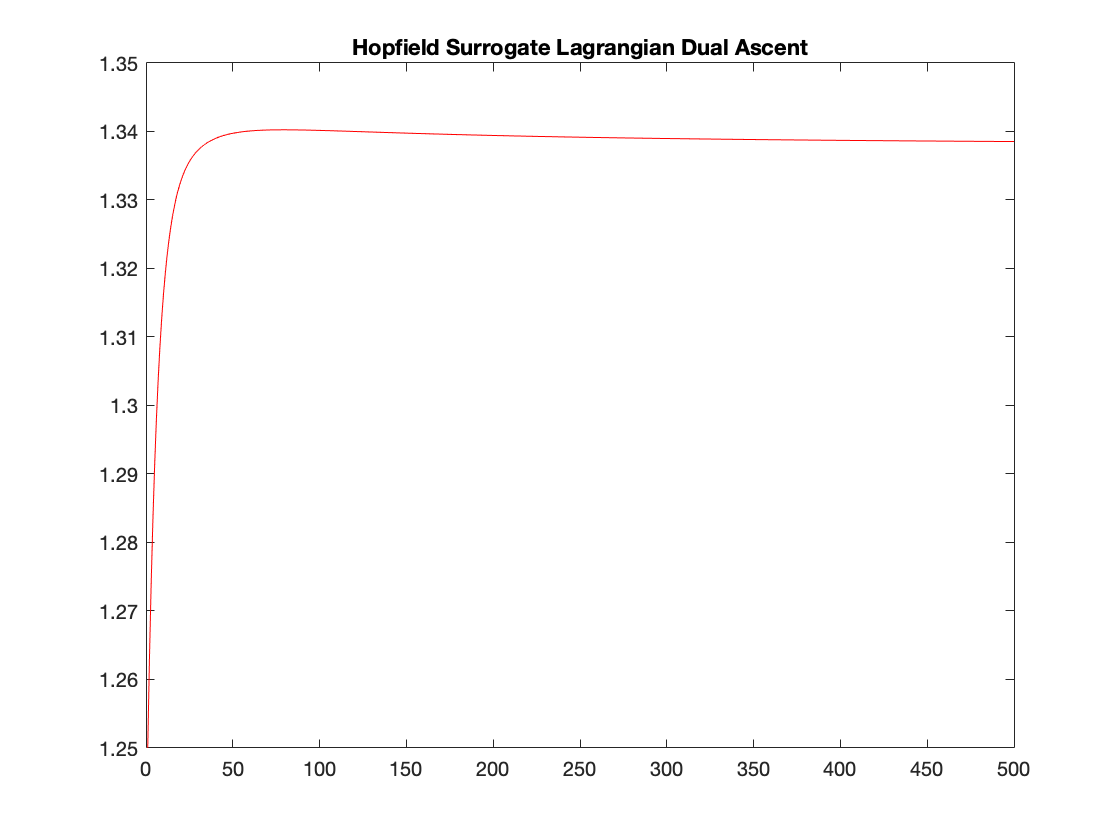

n=10;
rho=1;
step_size_hopfield=10^-2;
step_size_dual=10^-1;
num_dual_iter=500;

% We draw at random the parameters of the model
alpha=rand();
beta=rand();
p=rand(n,1);
x_0=round(rand(n,1));
y_0=rand(n,1).*x_0;
d=(1+0.1*(rand()-0.5))*sum(y_0);

% Initialization
lambda_1=0;
lambda_2=0;

% define activation
temp=[10*ones(n,1);ones(n,1)];
activation=@(z) 0.5*tanh(2*temp.*(z-0.5))+0.5;
inv_activation=@(y)0.5*(1./temp).*atanh(2*y-1)+0.5;

% define objective and gradient
cost=@(x,y) p'*y+0.5*alpha*norm(x-x_0)^2+0.5*beta*norm(y-y_0)^2;
objective=@(x,y,lambda_1,lambda_2) cost(x,y)+lambda_1*(x'*y-d)+0.5*rho*(x'*y-d)^2+lambda_2*(ones(n,1)'*y-d)+0.5*rho*(ones(n,1)'*y-d)^2; 
gradient=@(x,y,lambda_1,lambda_2) [alpha*(x-x_0)+lambda_1*y+rho*(y*y'*x-d*y);
    p+beta*(y-y_0)+lambda_1*x+rho*(x*x'*y-d*x)+lambda_2*ones(n,1)+rho*(ones(n,n)*y-d*ones(n,1))];
objective_hist=NaN*zeros(num_dual_iter,1);

for dual_iter=1:num_dual_iter
    % apply the hopfield method
    z=0.5*ones(2*n,1);
    z_prev=z+1;
    z_h=inv_activation(z);
    for iter=1:num_dual_iter
        z_prev=z;
        z_h=z_h-step_size_hopfield*gradient(z(1:n),z(n+1:2*n),lambda_1,lambda_2);
        z=activation(z_h);
    end
    objective_hist(dual_iter)=objective(z(1:n),z(n+1:2*n),lambda_1,lambda_2);
    lambda_1=lambda_1+step_size_dual*(z(1:n)'*z(n+1:2*n)-d);
    lambda_2=lambda_2+step_size_dual*(ones(n,1)'*z(n+1:2*n)-d);
end
x_hop=round(z(1:n),6);
y_hop=round(z(n+1:2*n),6);
figure(1)
plot(objective_hist,'r')
title('Hopfield Surrogate Lagrangian Dual Ascent')


cost_hopfield=cost(x_hop,y_hop);
disp(['The final cost of Dispatch using Hopfield is: ',num2str(cost_hopfield)])

The final cost of Dispatch using Hopfield is: 1.337


## Convex Relaxation Heuristic

Now we compare with convex heuristics. The nonconvexity arises from $x$, by finding it as a post process we can formulate the problem in a convex manner. We can start by solving


$$\min_y p^\top y+\frac{\beta}{2}\|y-y_0\|^2\\
1^\top y=d\\
\underline{y}\leq y \leq \overline{y}$$


And then find $x$ by looking at the components of $y$ that are not $0$, i.e. take $x=1(y\neq 0)$

cvx_begin quiet
variable y(n)
minimize(p'*y+0.5*beta*square_pos(norm(y-y_0)))
ones(1,n)*y==d
0<=y<=1
cvx_end
y_cvx=round(y,6);
x_cvx=(y_cvx~=0);
cost_cvx=cost(x_cvx,y_cvx);
disp(['The final cost of Dispatch using CVX is: ',num2str(cost_cvx)])

The final cost of Dispatch using CVX is: 2.4327
